## Serie de tiempo

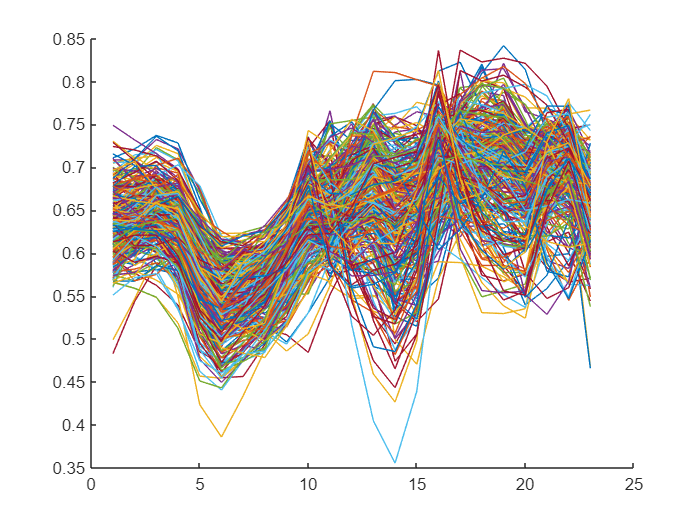

% indxs=find(info_hdf.anio>=2003 & info_hdf.anio<=2022);

indxs=find(info_hdf.anio==2022);
datos=arr_ndvi_sgf(:,:,indxs);
[alto,ancho,~]=size(datos);
figure; 
hold on
temp_Mediana=[];
temp_Mean=[];
temp_Mode=[];
temp_Range=[];
temp_Desv=[];
temp_Min=[];
temp_Max=[];
temp_Std=[];
temp_Mad=[];
temp_valor=[];
id=1;
for i=1:alto
     for j=1:ancho
        if(study_area(i,j)==1)
            serie = reshape(datos(i,j,:),[],1);
            plot(serie)
            temp_Mediana(id) =median(serie);
            temp_Mean(id)=mean(serie);
            temp_Mode(id)=mode(serie);
            temp_Range(id)=range(serie);
            temp_Desv(id)=std(serie);
            temp_Min(id)=min(serie);
            temp_Max(id)=max(serie);
            temp_Mad(id)=mad(serie);
            temp_valor(id)=1;
            id=id+1;
        end
    end
end
hold off


tab_data=table( temp_Mediana',temp_Mean',temp_Mode',temp_Range',temp_Desv',temp_Min',temp_Max',temp_Mad',temp_valor',VariableNames=["Mediana","Promedio","Moda","Rango","Desviacion","Minimos","Maximos","Mad","Valor"]);

Salvar los datos

writetable(tab_data,'M.xls')
